# Extraction de données d'une Base de Données

Pascal Denis - septembre 2020

Dans cet exercise, vous allez apprendre à extraire des données d'une matrice contenant les du [Perry's chemical engineer”s handbook](https://www.dawsonera.com/readonline/9780071593137) [1]. Cela vous permettra de savoir comment accèder à des données thermodynamiques et de comprendre la notion de structure associée.

#### Chargement de la base de données

% The file Perry.mat must be in your path
% Chargement de la base de données : 
% load Perry ou load Perry.mat fontionne

load Perry.mat;

Dans la zone Workspace, vous avez désormais : 

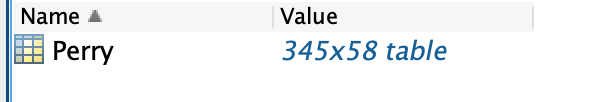

Fig. 1 Worksace

Il s'agit d'une table de 345 ligne et 58 colonnes contenant diverses informations. si vous faites un double clic sur Perry, les données de la tables s'ouvriront de la manière suivantes : 

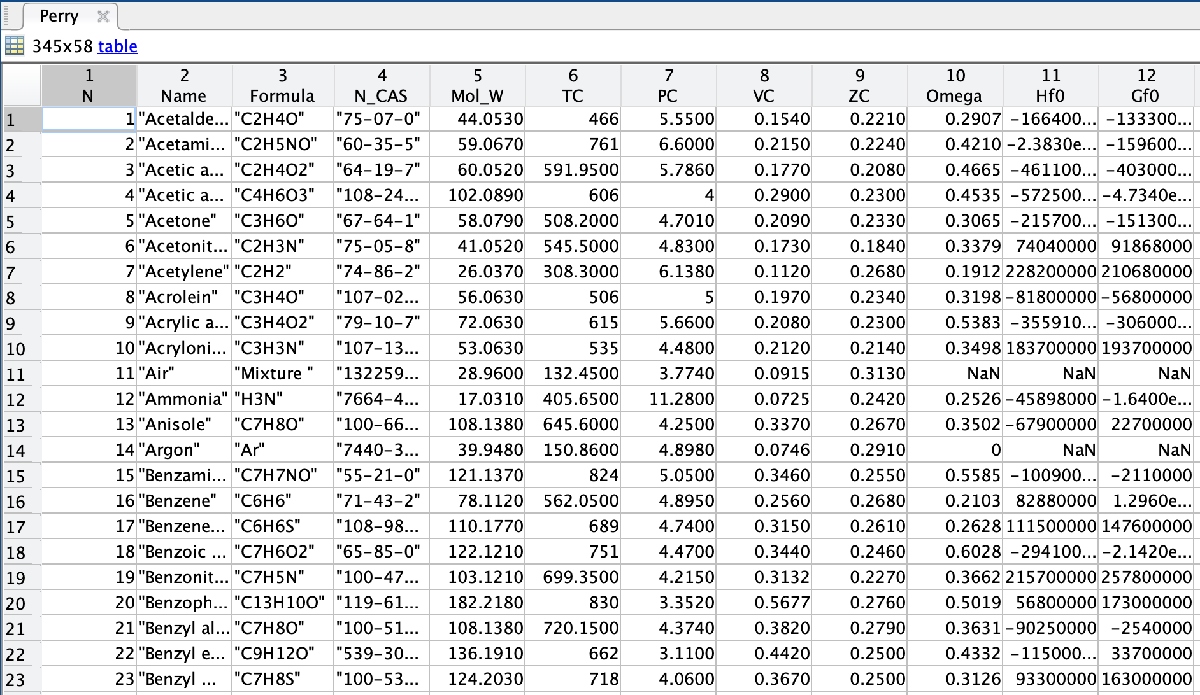

Par exemple pour i = 11, le composé est de l'air, c'est un moyen simple de connaitre un ID de produit dans la base. Vérifier que : 

- CO2 : 47 

- Méthane = 193 

- Eau (water)  = 342 

#### Structure de la base de données

% Pour accéder aux différentes données stockées, nous allons regarder les
% propriétés associées à cette table

Properties = Perry.Properties

Properties =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {1×58 cell}
    VariableDescriptions: {1×58 cell}
           VariableUnits: {1×58 cell}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


% Pour avoir la liste des variables sous la forme d'un vecteur ligne : 

Perry.Properties.VariableNames

ans = 1×58 cell array
    {'N'}    {'Name'}    {'Formula'}    {'N_CAS'}    {'Mol_W'}    {'TC'}    {'PC'}    {'VC'}    {'ZC'}    {'Omega'}    {'Hf0'}    {'Gf0'}    {'Sf0'}    {'DH_Comb'}    {'CP_Gas1'}    {'CP_Gas2'}    {'CP_Gas3'}    {'CP_Gas4'}    {'CP_Gas5'}    {'T_CP_Gas_min'}    {'CP_Gas_Tmin'}    {'T_CP_Gas_max'}    {'CP_Gas_Tmax'}    {'H_Vap1'}    {'H_Vap2'}    {'H_Vap3'}    {'H_Vap4'}    {'T_H_Vap_min'}    {'DH_Vap_min'}    {'T_H_Vap_max'}    {'DH_Vap_max'}    {'Eq_CP_Liq'}    {'CP_Liq1'}    {'CP_Liq2'}    {'CP_Liq3'}    {'CP_Liq4'}    {'CP_Liq5'}    {'T_CP_Liq_min'}    {'CP_Liq_Tmin'}    {'T_CP_Liq_max'}    {'CP_Liq_Tmax'}    {'C_Rho1'}    {'C_Rho2'}    {'C_Rho3'}    {'C_Rho4'}    {'T_Rho_min'}    {'Rho_min'}    {'T_Rho_max'}    {'Rho_max'}    {'C_Vap1'}    {'C_Vap2'}    {'C_Vap3'}    {'C_Vap4'}    {'C_Vap5'}    {'T_P_Vap_min'}    {'P_Vap_min'}    {'T_P_Vap_max'}    {'P_Vap_max'}


% et sous la forme d'un vecteur colonne, il suffit de prendre la

VariableNames = 58×1 cell array
    {'N'           }
    {'Name'        }
    {'Formula'     }
    {'N_CAS'       }
    {'Mol_W'       }
    {'TC'          }
    {'PC'          }
    {'VC'          }
    {'ZC'          }
    {'Omega'       }
    {'Hf0'         }
    {'Gf0'         }
    {'Sf0'         }
    {'DH_Comb'     }
    {'CP_Gas1'     }
    {'CP_Gas2'     }
    {'CP_Gas3'     }
    {'CP_Gas4'     }
    {'CP_Gas5'     }
    {'T_CP_Gas_min'}
    {'CP_Gas_Tmin' }
    {'T_CP_Gas_max'}
    {'CP_Gas_Tmax' }
    {'H_Vap1'      }
    {'H_Vap2'      }
    {'H_Vap3'      }
    {'H_Vap4'      }
    {'T_H_Vap_min' }
    {'DH_Vap_min'  }
    {'T_H_Vap_max' }


% transposée. 

VariableNames = Perry.Properties.VariableNames'

% Afin de connaitre le nom de la variable associée à une valeur entre 1 et
% 58 utiliser l'indicateur suivant : 

Indic    = 6

Indic = 6

Perry.Properties.VariableNames(Indic)

ans = 1×1 cell array
    {'TC'}


% vérifier alors que : 
% Perry.Properties.VariableNames(2) = {'Name'}
% Perry.Properties.VariableNames(6) = {'TC'}

% Les informations sur les unités de chaque variable sont disponibles
Indic    = 11

Indic = 11

Perry.Properties.VariableUnits(Indic)

ans = 1×1 cell array
    {'J/kmol'}


% Une description sommaire de la variable est disponible : 
% avec Indic = 11 vous avez l'enthalphie standard de formation gas du
% composé. 

Indic    = 23

Indic = 23

Perry.Properties.VariableDescriptions(Indic)

ans = 1×1 cell array
    {'Heat Capacity at Constant Pressure of Inorganic and Organic Compounds in the Ideal Gas State using Hyperbolic Functions at Maximal Temperature'}


#### Données de la Table

Extraction des données simples. 

% Si vous connaissez 

ID = 47

ID = 47


% Simple Information
 
Name = Perry.Name{ID}

Name = 'Carbon dioxide'

Mol_W = Perry.Mol_W(ID)

Mol_W = 44.0100

TC = Perry.TC(ID)

TC = 304.2100


% Coefficient de certaine fonction
% Exmple de la Pression de Vapeur utilisant une formulation de type  Riedel's Equation

C = [Perry.C_Vap1(ID) Perry.C_Vap2(ID) Perry.C_Vap3(ID) Perry.C_Vap4(ID) Perry.C_Vap5(ID) ];
disp(C);

   1.0e+03 *

    0.1405   -4.7350   -0.0213    0.0000    0.0010



#### Recherche de données dans la Table

En utilisant les fonctions classiques de MATLAB,  on peut sélection des données de manière assez simple et pratique. 

% search by #CAS
% Water Cas # = 7732-18-5

idx = ismember(Perry.N_CAS,'7732-18-5');
Perry.Name{idx}

% Search by molar weight
%  Mmol < 20 g/mol
idx = Perry.Mol_W<20;
Perry.Name(idx)

% Search by TC
% 300 < TC < 350 K 
idx = (Perry.TC<350) & (Perry.TC>300);
Perry.Name(idx)

% Search by TC and molar mass
% TC < 350 K and Mmol < 100
idx = (Perry.TC<350) & (Perry.Mol_W<20);
Perry.Name(idx)

## Propriétés Critiques

A l'aide de la Table 2-6 [1, P. 2-49] vérifier que : 

% # of Propane is 295
Name_cell = Perry.Name(295)
Name = Perry.Name{295}

Améliorer l'affichage

fprintf('Compounds Name 1 : %s \n',Name)
fprintf('Compounds Name 2 : %s \n',char(Name_cell))


disp(num2str('------------------------------------------------------'));
disp(Name_cell);

% Critical Temperature of Carbon monoxide
N = 49;
Name = Perry.Name{N};
TC = Perry.TC(N);

% Amélioration de l'affichage
fprintf('Critical Temperature of %s is %.2f K \n',Name,Perry.TC(N))

#### Calcul de la pression de vapeur saturante d'un composé et comparer avec la Table 2.9 [1, p.2-61]

Exemple de l'ammoniac (#12) à  -79.2 °C

ID = 12;
fprintf('Compounds Name : %s \n',Perry.Name{ID});
T_celsius = -79.2 ;% T in Celsius
T = T_celsius + 273.15;
Pref = 40 ;% mmHg
C = [Perry.C_Vap1(ID) Perry.C_Vap2(ID) Perry.C_Vap3(ID) Perry.C_Vap4(ID) Perry.C_Vap5(ID) ];
Psat = P_Sat_Perry(T,C) ;
Psat_mmHg = Psat / 101325 * 760;
fprintf('Saturated Pressure under T = %.2f °C is %.2f mmHg \n',T,Psat_mmHg);
fprintf('Reference Value is %.2f mmHg \n',Pref);
% Normal Boiling Point in °C for Ethanol
idx = find(ismember(Perry.Name,'Ethanol'))
C = [Perry.C_Vap1(idx) Perry.C_Vap2(idx) Perry.C_Vap3(idx) Perry.C_Vap4(idx) Perry.C_Vap5(idx) ];
P = P_Sat_Perry(T,C)
% Low Pressure isn't it ? 
% Remember thas T is always T_celsius = -79.2 


Calcul d'un point d'ébullition normal

% Normal Boiling Point in °C

func_NBP = @(T)P_Sat_Perry(T,C)-101325
T_NBP = fzero(func_NBP,300) - 273.15 

## Bibliography

[1] - Perry, R. H., & Green, D. W. (2008). Perry“s chemical engineer”s handbook; 8th ed. New York, NY: McGraw-Hill.